# Laborator 4

## Problema 1

Rezolvați pentru $\lambda =-100$ și diverși pași. 

$\Bigg\{$$\begin{array}{l}
y^{\prime } \left(t\right)=\lambda y\left(t\right),\\
y\left(0\right)=y_0 
\end{array}$, $\lambda =$constant, folosind metoda implicită a trapezului. Comparați cu soluția analitică $y\left(t\right)=y_0 e^{\lambda t}$.

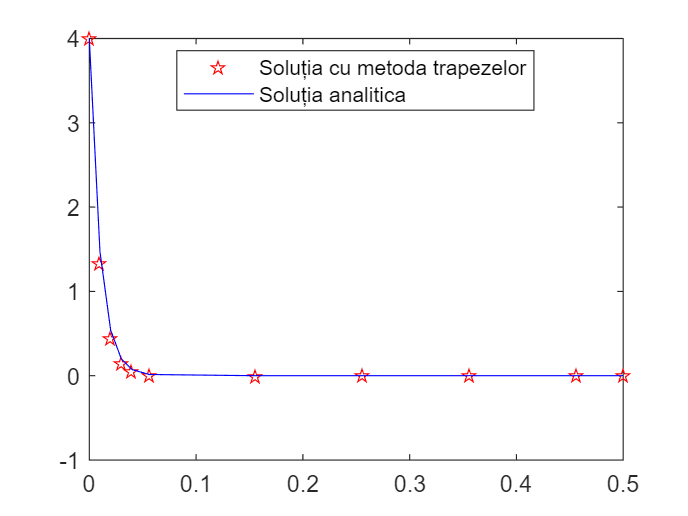

lambda = -100;
y0 = 4;

a = 0; b = 0.5; %capetele intervalului
hmax = 0.1; hmin = 0.01;
tol = 1e-3;


y(1) = y0; %conditia initiala
T(1) = a;
i = 1;
t = a;
f = @(y)lambda * y + 0 * t;
df = @(y)lambda + 0 * y + 0 * t;
h = 1;

while t < b
     R = 0.5 * h * y(i);
     if (R <= tol) || (h == hmin)
             T(i + 1) = T(i) + h;
             y(i + 1) = fNewtTrap(f, df, y(i), y(i), h, tol);
             i = i + 1;
             t = t + h;
             h = hmax;             
      else
         q = 0.8 * (tol * h / R) ^ 0.5;
         h = q * h;
         if h < hmin
             h = hmin;
         end
         if h > hmax
             h = hmax;
         end
     end     
     if(t + h > b)
         h = b - t;
     end
end

plot(T, y, 'rp') %reprezentam grafic solutia numerica
hold on
plot(T, y0 .* exp(lambda .* T), 'b')
legend("Soluția cu metoda trapezelor","Soluția analitica",Location="best")
hold off

## Problema 2

Rezolvați problema bilocală

$\Bigg\{$$\begin{array}{l}
{y^{\prime } }^{\prime } =y^{\prime } +2y+\cos \;x,0\le x\le \frac{\pi }{2},\\
y\left(0\right)=-0\ldotp 3,y\left(\frac{\pi }{2}\right)=-0\ldotp 1
\end{array}$. Comparați cu soluția exactă $y\left(x\right)=-\frac{1}{10}\left(\sin \;x+3\cos \;x\right)$.

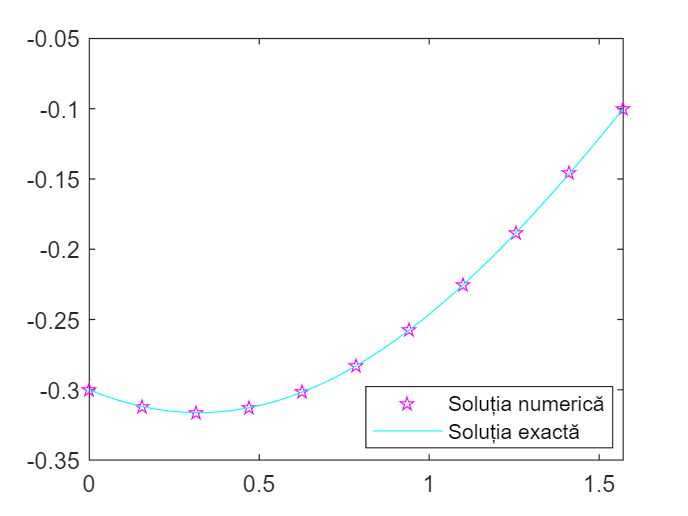

a = 0; b = pi / 2;
N = 11;
h = (b - a) / (N - 1);
A = zeros(N, N);
y = zeros(N, 1);
r = zeros(N, 1);
A(1, 1) = 1;
r(1) = -0.3; %boundary value in the point a
for i = 2 : N-1
A(i, i-1) = 1 + h / 2;
A(i, i) = -2 * (h ^ 2 + 1);
A(i, i+1) = 1 - h / 2;
r(i) = h * h * cos((i - 1) * h);
end
A(N, N) = 1;
r(N) = -0.1; %boundary value in the point b
y = A \ r;%solve the system
x = a : h : b;
plot(x, y, 'mp');%plot the numerical solution
hold on
x = a: 0.1 * h : b;
plot(x, -0.1 .* (sin(x) + 3 .* cos(x)),'Cyan'); %plot the exact solution
legend("Soluția numerică", "Soluția exactă",Location="best")
hold off

## Funcții utilizate

### fptrap

function yp=fptrap(f,y,h)
%derivata functei obtinute pentru metoda trapezului
yp=1-0.5*h*f(y);
end

function yp=ftrap(f,y,yi,h)
%functia obtinuta dupa aplicarea metodei trapezului
yp=y-yi-0.5*h*(f(yi)+f(y));
end

function y1=fNewtTrap(f,df,y0,yi,h,tol)
err=1;
y1=y0;
while(err>tol) 
   y1=y0-ftrap(f,y0,yi,h)/fptrap(df,y0,h);
   err=abs(y1-y0);
   y0=y1;
end
end